# Interpolacja funkcj z = f(x,y)

Określenie wspolrzędnych węzlow (xw, yw)


clc
clear all
close all

gestosc = 0.99;
xw = [-5:gestosc:5];
yw = [-5:gestosc:5];
[XW,YW] = meshgrid(xw,yw);

Obliczenie wartosci funkcji w wezlach (albo na podstawie tablicy wartości albo korzystajac ze wzoru)

ZW = @(XW,YW) sin(XW.^2 + YW.^2) ./ (XW.^2 + YW.^2);

`Narysowanie wezlow w przestrzeni`

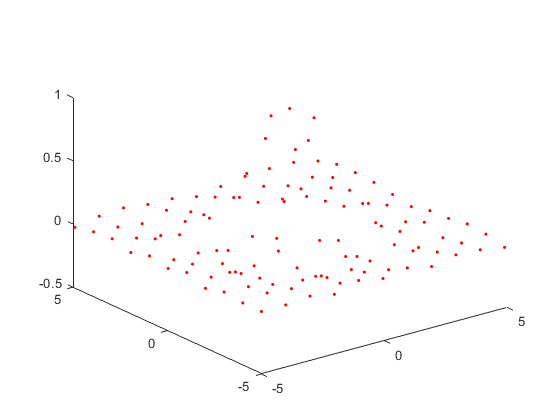

plot3(XW,YW,ZW(XW,YW),'r.')

Przygotowanie gesrych wektorow na potrzeby interpolacji

dzielnik = 2;
xi = xw(1):gestosc/dzielnik:xw(end);
yi = yw(1):gestosc/dzielnik:yw(end);

[XI,YI] = meshgrid(xi,yi);

Interpolacja

metoda = "nearest"

metoda = "nearest"

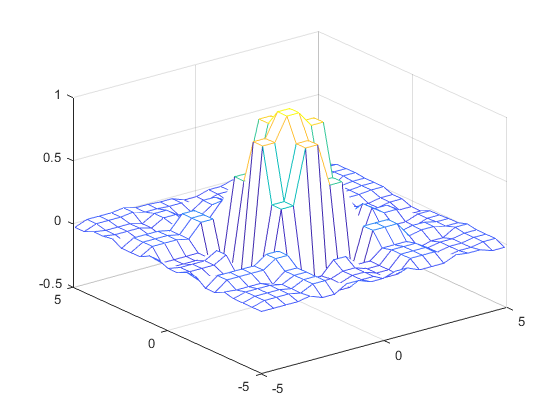

ZI = interp2(XW,YW,ZW(XW,YW),XI,YI,metoda);
mesh(XI,YI,ZI)

Sprawdzenie (najważniejszy wykres i jedyny z punktu widzenia interpolacji: wezly + funkcja)

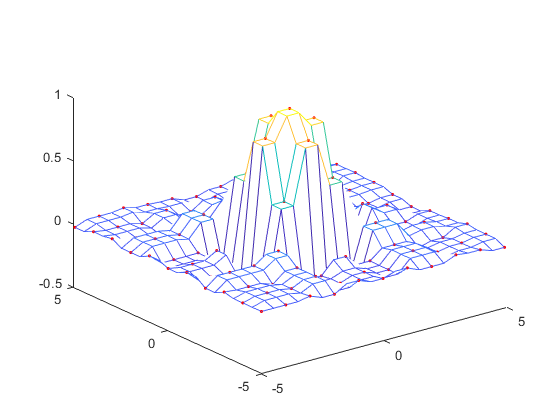

plot3(XW,YW,ZW(XW,YW),'r.')
hold on
mesh(XI,YI,ZI)

### Zadanie 1, 1.2 - wykresy

z = [0, 6.3, 8.8, 10.1, 11.1; 0, 4.5, 6.2, 7.3, 8; 0, 3.9, 5.15, 6, 6.6; 0, 3.2, 4.5, 5.2, 5.9; 0, 3, 4.05, 4.85, 5.2]

z =          0    6.3000    8.8000   10.1000   11.1000
         0    4.5000    6.2000    7.3000    8.0000
         0    3.9000    5.1500    6.0000    6.6000
         0    3.2000    4.5000    5.2000    5.9000
         0    3.0000    4.0500    4.8500    5.2000


x = [1, 5, 9, 13, 17]

x =      1     5     9    13    17


y = [0.01, 0.02, 0.03, 0.04, 0.05]

y =     0.0100    0.0200    0.0300    0.0400    0.0500


xx = 1:0.1:17

xx =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


yy = [0.01:0.001:0.05]

yy =     0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


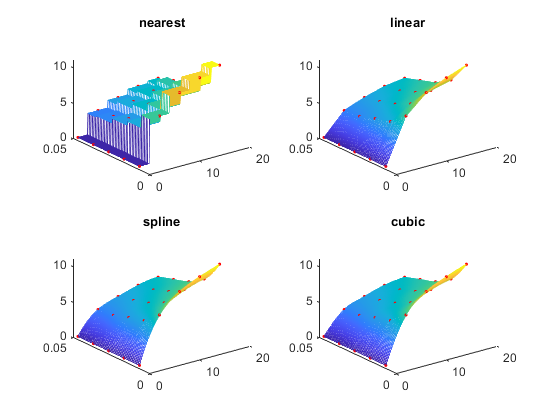

[X,Y]=meshgrid(x,y);
[XX,YY]=meshgrid(xx,yy);

I1=interp2(X,Y,z,XX,YY,'nearest');
I2=interp2(X,Y,z,XX,YY,'linear');
I3=interp2(X,Y,z,XX,YY,'spline');
I4=interp2(X,Y,z,XX,YY,'cubic');


subplot(2,2,1)
plot3(X,Y,z,'.r')
hold on
mesh(XX,YY,I1)
title('nearest')

hold on

subplot(2,2,2)
plot3(X,Y,z,'.r')
hold on
mesh(XX,YY,I2)
title('linear')
hold on

subplot(2,2,3)
plot3(X,Y,z,'.r')
hold on
mesh(XX,YY,I3)
title('spline')
hold on

subplot(2,2,4)
plot3(X,Y,z,'.r')
hold on
mesh(XX,YY,I4)
title('cubic')
hold off

## Zadanie 1.2, 1.3

XX=[7 11 15];
YY=[0.05 0.03 0.01];

I=[interp2(X,Y,z,XX,YY,'nearest'); interp2(X,Y,z,XX,YY,'linear'); interp2(X,Y,z,XX,YY,'spline'); interp2(X,Y,z,XX,YY,'cubic')]

I =     4.0500    6.0000   11.1000
    3.5250    5.5750   10.6000
    3.6328    5.5828   10.6078
    3.6625    5.6156   10.6375


blad=sqrt(((I(:,1)-3.6).^2 + (I(:,2)-5.6).^2 + (I(:,3)-10.6).^2))

blad =     0.7826
    0.0791
    0.0379
    0.0745


## Zadanie 2

z = [0. 8.8, 11.1; 0, 5.15, 6.6; 0, 4.05, 5.2]

z =          0    8.8000   11.1000
         0    5.1500    6.6000
         0    4.0500    5.2000


x = [1, 9, 17]

x =      1     9    17


y = [0.01, 0.03, 0.05]

y =     0.0100    0.0300    0.0500


xx = 1:0.1:17

xx =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


yy = [0.01:0.001:0.05]

yy =     0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


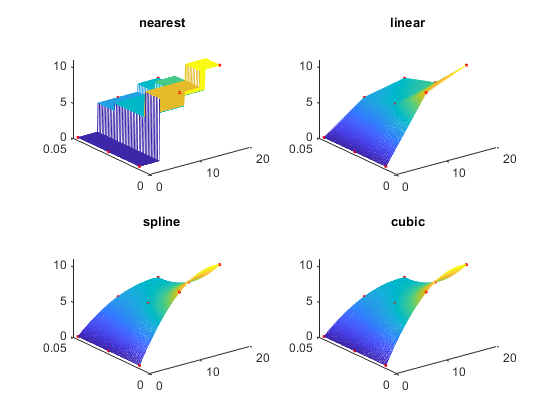

[X,Y]=meshgrid(x,y);
[XX,YY]=meshgrid(xx,yy);

I1=interp2(X,Y,z,XX,YY,'nearest');
I2=interp2(X,Y,z,XX,YY,'linear');
I3=interp2(X,Y,z,XX,YY,'spline');
I4=interp2(X,Y,z,XX,YY,'cubic');

figure()
subplot(2,2,1)
plot3(X,Y,z,'.r')
hold on
mesh(XX,YY,I1)
title('nearest')

hold on

subplot(2,2,2)
plot3(X,Y,z,'.r')
hold on
mesh(XX,YY,I2)
title('linear')
hold on

subplot(2,2,3)
plot3(X,Y,z,'.r')
hold on
mesh(XX,YY,I3)
title('spline')
hold on

subplot(2,2,4)
plot3(X,Y,z,'.r')
hold on
mesh(XX,YY,I4)
title('cubic')

XX=[7 11 15];
YY=[0.05 0.03 0.01];

I=[interp2(X,Y,z,XX,YY,'nearest'); interp2(X,Y,z,XX,YY,'linear'); interp2(X,Y,z,XX,YY,'spline'); interp2(X,Y,z,XX,YY,'cubic')]

I =     4.0500    5.1500   11.1000
    3.0375    5.5125   10.5250
    3.3094    5.8594   11.1344
    3.3094    5.8594   11.1344


blad=sqrt(((I(:,1)-3.6).^2 + (I(:,2)-5.6).^2 + (I(:,3)-10.6).^2)./3)

blad =     0.4673
    0.3315
    0.3818
    0.3818
